# Recycling Analysis Demo

Use WasteAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Set the parameters and get the RecyclingAnalysis results

WasteFlows=convertCharsToStrings(data.WasteData.Flows);
param.ActiveWaste=convertStringsToChars(WasteFlows(1));
States=convertCharsToStrings(data.States);
param.State=convertStringsToChars(States(3));
param.CostTables='ALL';
Samples=convertCharsToStrings(data.ResourceSamples);
param.ResourceSample=convertStringsToChars(Samples(1));
res=WasteAnalysis(data,param);

#### Show the Results

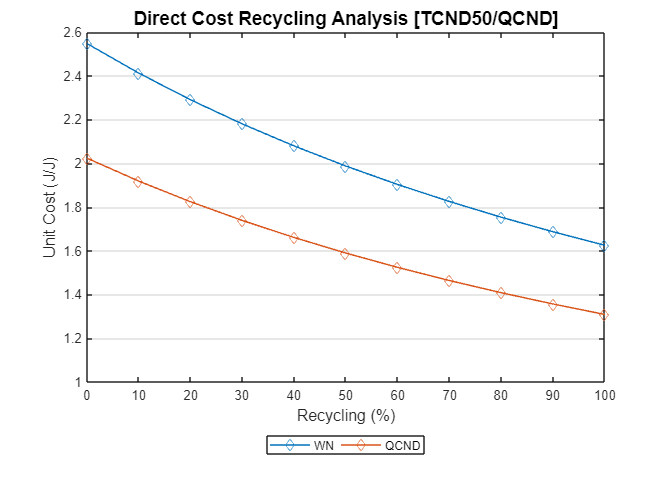

showGraph(res,cType.Tables.WASTE_RECYCLING_DIRECT);

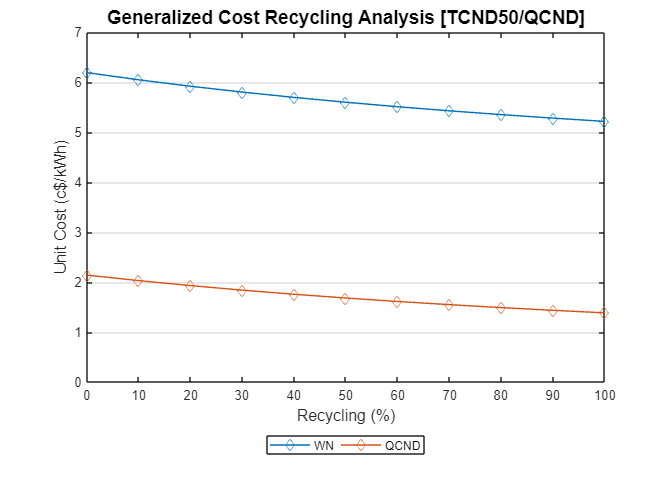

showGraph(res,cType.Tables.WASTE_RECYCLING_GENERAL);

printResults(res);

Waste Definition Table

Key   Type              Recycling (%)
——————————————————————————————————————
QCND  IRREVERSIBILITY         0.00


Waste Allocation Table  (%)

 Key       QCND
————————————————
 BLR      94.53
 TRB       2.62
 IHE       1.37
 PMP       1.48


Direct Cost Recycling Analysis (J/J)

 Recycle (%)          WN       QCND
————————————————————————————————————
      0           2.5471     2.0232
     10           2.4119     1.9184
     20           2.2900     1.8239
     30           2.1795     1.7384
     40           2.0789     1.6604
     50           1.9870     1.5892
     60           1.9026     1.5238
     70           1.8249     1.4636
     80           1.7531     1.4080
     90           1.6866     1.3564
    100           1.6247     1.3085


Generalized Cost Recycling Analysis (c$/kWh)

 Recycle (%)          WN       QCND
————————————————————————————————————
      0           6.1867     2.1383
     10           6.0438     2.0275
     20           5.9149     1.927